## 0. Parámetros Físicos

Long = 20;              % Distancia de fibra en km (Ej. 25km, 50km)
alpha = 0.2;         % Atenuación de la fibra estándar (dB/km)
Va = 4;              % Varianza de modulación de Alice (VA). Típico: 4-20 SNU.
T = 10^(-alpha * Long / 10) %Transmitancia

T = 0.3981

% Parámetros de Ruido
vel = 0.05;          % Ruido electrónico del detector (0.05 = 5% del shot noise)
xi = 0.01;           % Ruido de exceso a la entrada (Excess Noise). Típico: 0.01
% Tamaños
n = 26112

n = 26112

max_iter = 60

max_iter = 60

N_pulsos = 100000 %Número de pulsos que vamos a generar (tiene que ser mayor para generar varias veces)

N_pulsos = 100000

## 1. Generación (Alice)

%Generamos los números Aleatorios de Alice
q_Alice = sqrt(Va)*randn(N_pulsos, 1)

q_Alice =    -4.1150
    2.4491
   -2.4426
   -2.8593
   -3.5106
   -3.1434
    4.4455
   -0.3879
   -0.7719
   -0.8056
   -1.7794
    1.2127
   -0.4930
    1.3751
   -0.8860


p_Alice = sqrt(Va)*randn(N_pulsos, 1)

p_Alice =    -1.1684
    2.5973
   -0.3896
   -0.9384
   -0.7188
    1.2160
    1.6529
    2.8276
    0.0732
    0.2362
   -0.3322
   -1.6973
   -0.2174
   -2.4471
    0.0257


Xa = zeros(2 * N_pulsos, 1)

Xa =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% Intercalado (Interleaving)
Xa(1:2:end) = q_Alice; % Posiciones impares: Q
Xa(2:2:end) = p_Alice; % Posiciones pares: P

%Simulación de Ruido
%variables de ruido
var_noise = 1 + vel + T * xi %varianza del ruido

var_noise = 1.0540

std_noise = sqrt(var_noise) %desviación típica del ruido

std_noise = 1.0266

% ruido como tal
z_noise_p = std_noise * randn(N_pulsos, 1)

z_noise_p =     0.1694
   -0.2336
   -0.3836
   -0.8448
   -1.1885
   -2.2276
   -0.9999
    1.1984
    0.4876
    0.0329
   -0.8463
    0.2542
    2.3426
    0.5301
   -1.4641


z_noise_q = std_noise * randn(N_pulsos, 1)

z_noise_q =    -0.1029
   -0.4825
    0.8709
    0.4491
    0.6983
    1.0114
   -0.0059
   -0.9195
   -1.5390
   -0.1140
    1.0281
   -0.2251
   -0.2357
    0.8864
   -0.5291


## 2. Recepción (Bob)

p_Bob = sqrt(T) * p_Alice + z_noise_p

p_Bob =    -0.5678
    1.4052
   -0.6294
   -1.4370
   -1.6421
   -1.4604
    0.0430
    2.9825
    0.5339
    0.1819
   -1.0559
   -0.8167
    2.2054
   -1.0139
   -1.4478


q_Bob = sqrt(T) * q_Alice + z_noise_q

q_Bob =    -2.6993
    1.0628
   -0.6703
   -1.3550
   -1.5168
   -0.9719
    2.7991
   -1.1642
   -2.0260
   -0.6223
   -0.0946
    0.5400
   -0.5467
    1.7540
   -1.0881


Yb = zeros(2*N_pulsos,1)

Yb =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Yb(1:2:end) = q_Bob; % Posiciones impares: Q
Yb(2:2:end) = p_Bob; % Posiciones pares: P

## 2.1 Representación de Valores y cálculo parámetros interesantes

%Todo esto es muy extra de chati
% Potencia de señal recibida / Potencia de ruido total
Signal_Power_Rx = T * Va;
Noise_Power_Rx  = var_noise;

SNR_lineal = Signal_Power_Rx / Noise_Power_Rx;
SNR_dB = 10 * log10(SNR_lineal)

SNR_dB = 1.7923

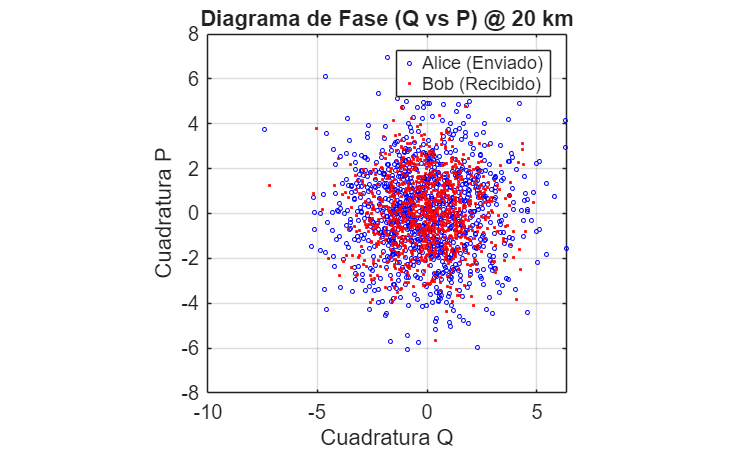


figure;
% Mostramos solo los primeros 1000 puntos para no saturar la gráfica
plot(q_Alice(1:1000), p_Alice(1:1000), 'bo', 'MarkerSize', 2); hold on;
plot(q_Bob(1:1000), p_Bob(1:1000), 'r.', 'MarkerSize', 4);
legend('Alice (Enviado)', 'Bob (Recibido)');
title(['Diagrama de Fase (Q vs P) @ ' num2str(Long) ' km']);
xlabel('Cuadratura Q'); ylabel('Cuadratura P');
axis square; grid on;

## 3. Generación de H

%% 3. GENERACIÓN DE MATRIZ H (LDPC 5G NR)
% -------------------------------------------------------------------------
% Cargar Base Graph 1 del estándar 5G NR-LDPC
Z = 384;                            % Factor de lifting
baseGraphFile = 'C:\Users\usser\OneDrive - Universidad Politécnica de Madrid\INDUSTRIALES I DANI\GRADO\TFG\LDPC\NR-LDPC-BG-master\NR-LDPC-BG-master\NR_1_1_384.txt';

% Leer la matriz base desde archivo
BaseGraph = load(baseGraphFile);
[mb, nb] = size(BaseGraph);         % BG1: 46×68

% Dimensiones finales de H
M = mb * Z;                         % 17,664 filas (ecuaciones de paridad)
N_ldpc = nb * Z;                    % 26,112 columnas (bits totales)

fprintf('Matriz Base: %d×%d, Z=%d → H: %d×%d\n', mb, nb, Z, M, N_ldpc);

Matriz Base: 46×68, Z=384 → H: 17664×26112



% Expansión de la matriz (lifting) usando matrices sparse
% Pre-calcular número de elementos no nulos para eficiencia
num_nonzero_blocks = sum(BaseGraph(:) >= 0);
nnz_total = num_nonzero_blocks * Z;

% Pre-asignar arrays para construcción sparse eficiente
row_indices = zeros(nnz_total, 1);
col_indices = zeros(nnz_total, 1);
values = ones(nnz_total, 1);

idx = 1;
for i = 1:mb
    for j = 1:nb
        shift_val = BaseGraph(i, j);
        if shift_val >= 0
            % Índices de la submatriz identidad rotada
            row_base = (i-1) * Z;
            col_base = (j-1) * Z;
            
            % Generar índices de la identidad circulante
            for k = 1:Z
                row_indices(idx) = row_base + k;
                col_indices(idx) = col_base + mod(k - 1 + shift_val, Z) + 1;
                idx = idx + 1;
            end
        end
    end
end

% Construir matriz sparse
H = sparse(row_indices, col_indices, values, M, N_ldpc)

H = 17664×26112 sparse double matrix (121344 nonzeros)
        (78,1)              1
       (693,1)              1
       (948,1)              1
      (1261,1)              1
      (1589,1)              1
      (2110,1)              1
      (2411,1)              1
      (3064,1)              1
      (3150,1)              1
      (3475,1)              1
      (4561,1)              1
      (4916,1)              1
      (5064,1)              1
      (5619,1)              1
      (5904,1)              1
      (6653,1)              1
      (7536,1)              1
      (7878,1)              1
      (8803,1)              1
      (9303,1)              1
     (10298,1)              1
     (10915,1)              1
     (11746,1)              1
     (12571,1)              1
     (13211,1)              1
     (13999,1)              1
     (14792,1)              1
     (15570,1)              1
     (16400,1)              1
     (17201,1)              1
        (79,2)              1
       (694,2) 


fprintf('Matriz H generada: %d elementos no nulos (densidad: %.4f%%)\n', nnz(H), 100*nnz(H)/(M*N_ldpc));

Matriz H generada: 121344 elementos no nulos (densidad: 0.0263%)


## 4. Estimación de parámetros

%Generamos los distintos vectores que necesitamos
Xr = Xa(1:2:2*n) %Los valores de X que vamos a usar para la reconciliación

Xr =    -4.1150
    2.4491
   -2.4426
   -2.8593
   -3.5106
   -3.1434
    4.4455
   -0.3879
   -0.7719
   -0.8056
   -1.7794
    1.2127
   -0.4930
    1.3751
   -0.8860


Xp = Xa(2:2:2*n) %Los valores de X que vamos a usar para la estimación de parámetros

Xp =    -1.1684
    2.5973
   -0.3896
   -0.9384
   -0.7188
    1.2160
    1.6529
    2.8276
    0.0732
    0.2362
   -0.3322
   -1.6973
   -0.2174
   -2.4471
    0.0257


Yr = Yb(1:2:2*n) %Los valores de Y que vamos a usar para la reconciliación

Yr =    -2.6993
    1.0628
   -0.6703
   -1.3550
   -1.5168
   -0.9719
    2.7991
   -1.1642
   -2.0260
   -0.6223
   -0.0946
    0.5400
   -0.5467
    1.7540
   -1.0881


Yp = Yb(2:2:2*n) %Los valores de Y que vamos a usar para la estimación de parámetros

Yp =    -0.5678
    1.4052
   -0.6294
   -1.4370
   -1.6421
   -1.4604
    0.0430
    2.9825
    0.5339
    0.1819
   -1.0559
   -0.8167
    2.2054
   -1.0139
   -1.4478


%Estimamos T
Cov_xy = cov(Xp, Yp) %matriz de covarianzas

Cov_xy =     4.0689    2.5638
    2.5638    2.6581


covarianza_xy = Cov_xy(1, 2) 

covarianza_xy = 2.5638

varianza_x = var(Xp)

varianza_x = 4.0689

T_estimada = (covarianza_xy / varianza_x)^2

T_estimada = 0.3970


%Estimación del ruido residual
sigma2 = var(Yp - sqrt(T_estimada)*Xp)

sigma2 = 1.0427

z_est = (sigma2 - 1 - vel)/T_estimada

z_est = -0.0185

## 5. Cálculo del Síndrome

%Calculamos el síndrome
Kb = zeros(n, 1)

Kb =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Kb(Yr <= 0) = 1; 
Kb(Yr > 0)  = 0;
S = mod(H * Kb, 2);

## 6. Reconciliación Inversa

### 6.1. Inicialización

% calculamos LLR(0)
L = sqrt(T_estimada) * Xr + z_est

L =    -2.6113
    1.5247
   -1.5576
   -1.8201
   -2.2305
   -1.9992
    2.7826
   -0.2629
   -0.5049
   -0.5261
   -1.1397
    0.7457
   -0.3291
    0.8480
   -0.5768



% inicializamos L
L = LLR;
Q = H.*L' %esto proyecta el vector L sobre las columnas de H

Q = 17664×26112 sparse double matrix (121344 nonzeros)
        (78,1)             0.1361
       (693,1)             0.1361
       (948,1)             0.1361
      (1261,1)             0.1361
      (1589,1)             0.1361
      (2110,1)             0.1361
      (2411,1)             0.1361
      (3064,1)             0.1361
      (3150,1)             0.1361
      (3475,1)             0.1361
      (4561,1)             0.1361
      (4916,1)             0.1361
      (5064,1)             0.1361
      (5619,1)             0.1361
      (5904,1)             0.1361
      (6653,1)             0.1361
      (7536,1)             0.1361
      (7878,1)             0.1361
      (8803,1)             0.1361
      (9303,1)             0.1361
     (10298,1)             0.1361
     (10915,1)             0.1361
     (11746,1)             0.1361
     (12571,1)             0.1361
     (13211,1)             0.1361
     (13999,1)             0.1361
     (14792,1)             0.1361
     (15570,1)             

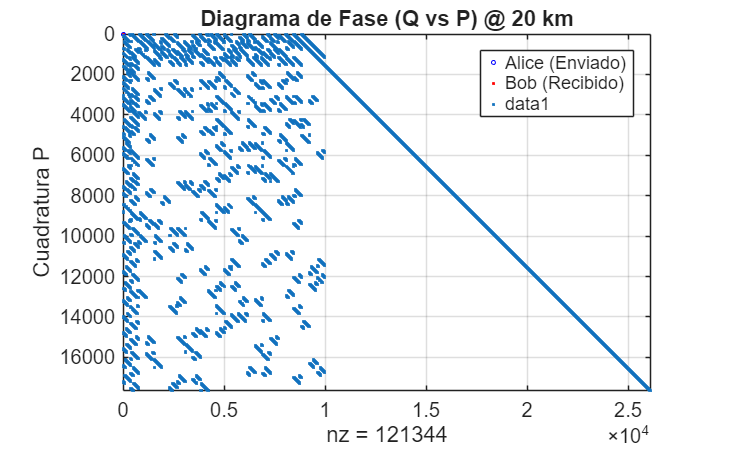

spy(Q)

### 6.2. Busqueda de los valores mínimos de cada Check-Node

[filas_H, columnas_H, ~] = find(H)

filas_H =           78
         693
         948
        1261
        1589
        2110
        2411
        3064
        3150
        3475
        4561
        4916
        5064
        5619
        5904


columnas_H =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


num_edges = length(filas_H)

num_edges = 121344

%Buscamos el mínimo de cada columna
[filaQ, columnaQ, val] = find(Q) %me devuelve todos los elementos distintos de 0

filaQ =           78
         693
         948
        1261
        1589
        2110
        2411
        3064
        3150
        3475
        4561
        4916
        5064
        5619
        5904


columnaQ =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


val =     0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361


val_abs = abs(val) %valor absoluto

val_abs =     0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361
    0.1361


[B, sort_idx] = sortrows([filaQ, val_abs], [1 2]) %me devuelve todos los índices de los 2 números mayores

B = 1.0e+04 *

    0.0001    0.0000
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0002
    0.0001    0.0002
    0.0001    0.0002
    0.0001    0.0002
    0.0001    0.0002
    0.0001    0.0002
    0.0001    0.0002
    0.0001    0.0002
    0.0001    0.0003


sort_idx =        82251
       35905
       56269
       51073
        9211
       89425
       98689
       33365
       93663
       53315
       29020
       64600
       94093
       22623
       85357


%Buscamos cuál es el orden de los elementos
filas_sorted = filaQ(sort_idx)

filas_sorted =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


cols_sorted = columnaQ(sort_idx)

cols_sorted =         7155
        2521
        4626
        4129
         308
        8011
        8833
        2102
        8411
        4334
        1522
        5350
        8450
         819
        7477


val_abs_sorted = val_abs(sort_idx) %están ordenados por filas

val_abs_sorted =     0.4047
    0.6098
    0.6857
    1.1198
    1.4075
    1.4439
    1.7019
    1.7578
    1.7724
    1.7790
    1.7826
    2.0009
    2.1444
    2.3090
    3.0818


%Encontramos el valor más alto de cada check-node (fila)
[unique_filas, primer_idx] = unique(filas_sorted, 'first')

unique_filas =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15


primer_idx =      1
    20
    39
    58
    77
    96
   115
   134
   153
   172
   191
   210
   229
   248
   267


%Guardamos todos los mínimos en una matriz y que columna tenía ese mínimo
min1_vals(unique_filas) = val_abs_sorted(primer_idx)

min1_vals =     0.4047    0.3295    0.0845    0.1277    0.5375    0.0011    0.3260    0.0516    0.1048    0.2552    0.0346    0.0320    0.0670    0.2423    0.0483    0.0748    0.1045    0.2875    0.0982    0.0120    0.2606    0.2933    0.0395    0.0001    0.0249    0.0334    0.0689    0.1375    0.0959    0.1283    0.1894    0.0895    0.1696    0.0012    0.2235    0.2099    0.1924    0.1300    0.1102    0.1540    0.0846    0.3409    0.0914    0.0953    0.2561    0.0041    0.2324    0.0352    0.0086    0.1958


min1_cols(unique_filas) = cols_sorted(primer_idx)

min1_cols =         7155         309        2104         311        3778        8016        8839        6258        1530        5985        4636        7488        4638        1535        8025        3789        4642        8467         422        7496        5996        5371        2543        8434        8435        6276        7503        8038         336         337        4656        2552        6008        8444        3808        6286        3810        4663        3812         347        8873        8874        5008        8070        5010        4174        8879        2149        6299        8060


%min1_filas(unique_filas) = filas_sorted(primer_idx)%no me aporta info
%nueva
min2_vals(unique_filas) = val_abs_sorted(primer_idx + 1)

min2_vals =     0.6098    0.4109    0.1603    0.2432    0.5883    0.0812    0.4664    0.2557    0.2388    0.2604    0.3322    0.1034    0.1355    0.5773    0.0809    0.2040    0.2879    0.3282    0.2352    0.1948    0.3973    0.5447    0.2528    0.2949    0.0714    0.1066    0.2066    0.2661    0.1603    0.3194    0.2282    0.1534    0.2024    0.0175    0.4656    0.3009    0.2266    0.1894    0.2476    0.3798    0.1541    0.5177    0.3567    0.2394    0.2968    0.0170    0.2638    0.0686    0.3552    0.5045


### 6.3 Cálculo de los valores de cada elemento de R

% 1. Recuperamos los índices originales de la matriz H


% 2. Pre-asignamos el vector de valores para R (magnitudes)
R_mags = zeros(num_edges, 1)

R_mags =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% 3. Asignación vectorizada (Lógica Min-Sum)
% Para cada arista (conexión), tenemos que decidir si usamos min1 o min2.
% Usamos min1 por defecto. SOLO si la columna coincide con min1_cols, usamos min2.

% Expandimos los mínimos al tamaño de las aristas para poder comparar
% rows es el índice de fila de cada arista. Usémoslo para mapear.

vals_min1_expanded = min1_vals(filaQ) 

vals_min1_expanded =     0.0349    0.0118    0.0438    0.0337    0.1361    0.1361    0.1361    0.1361    0.1361    0.0697    0.1361    0.1361    0.1361    0.1361    0.1361    0.1361    0.1361    0.1361    0.1361    0.1361    0.0487    0.1361    0.1279    0.1361    0.1361    0.1361    0.0670    0.0450    0.1361    0.1361    0.2156    0.0970    0.0009    0.0381    0.7263    0.0264    0.2822    1.1833    0.1967    0.0501    0.4286    0.3637    0.2539    0.9128    0.1073    1.0254    0.1395    0.3891    0.8544    0.1511


cols_sorted

cols_sorted =         7155
        2521
        4626
        4129
         308
        8011
        8833
        2102
        8411
        4334
        1522
        5350
        8450
         819
        7477


vals_min2_expanded = min2_vals(filaQ)

vals_min2_expanded =     0.1361    0.1279    0.0589    0.1098    1.1172    0.1471    0.1380    0.4492    0.2623    0.1361    0.2750    0.3891    0.1476    0.2837    0.3098    0.3818    1.2991    0.4656    0.1373    1.5443    0.1361    0.4066    0.1361    1.4803    0.9074    0.2584    0.1361    0.1361    0.4599    0.7302    0.2623    0.2423    0.3568    0.1833    1.0993    0.2895    0.3634    1.5250    0.6057    0.3219    0.5155    0.8274    0.2643    1.5250    0.4596    1.3551    1.1413    0.6371    0.9533    0.8168



% Lógica de selección:
% Creamos una máscara lógica: ¿Es esta columna la que tenía el mínimo?
is_min_col = (columnaQ' == cols_min1_expanded)

Unrecognized function or variable 'cols_min1_expanded'.

find(is_min_col)

% Asignamos valores
R_mags(~is_min_col) = vals_min1_expanded(~is_min_col); % Caso normal: usa min1
R_mags(is_min_col)  = vals_min2_expanded(is_min_col);  % Caso excepción: usa min2

% 4. Aplicar el factor de escala (Scaled Min-Sum)
alpha = 0.75; % O el valor que estés usando
R_mags = R_mags * alpha

### 6.4. Cálculo del signo de cada elemento

%2.2 Calculamos los signos de cada elemento
[rows, cols] = find(H);
vals_Q = Q(sub2ind(size(Q), rows, cols)) %obtengo todos los valores de los edges
signs_Q = sign(vals_Q)
signs_Q(signs_Q == 0) = 1; %para asegurarme de que no hay ceros
% Creamos una matriz lógica donde 1 indica que el valor es negativo
is_negative_sparse = sparse(rows, cols, double(signs_Q < 0), size(H,1), size(H,2))
% Sumamos por filas para ver cuántos negativos tiene cada Check Node
num_negatives_per_row = sum(is_negative_sparse, 2)
% Calculamos el signo global de la fila (-1 elevado al número de negativos)
row_parity_signs = (-1) .^ num_negatives_per_row 
%2.3 Aplicamos el Síndrome (S)
syndrome_adjustment = (-1) .^ S
global_row_signs = row_parity_signs .* syndrome_adjustment
signs_expanded = global_row_signs(rows)
final_signs = signs_expanded .* signs_Q

R = final_signs .* R_mags